Generate a reaction trace plot from a single arm design and target shape scenario:

%%% Define baseline parameters:
rho_outer = 0.08;
rho_inner = 0.015;

% Actuator position radii and the associated moment-arm matrix
rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
    1, 1, 1, 1;
    0, 0, 0, 0;
    -rhos;
    ];

l_0 = 0.5;

g_0 = Pose2.hat([0, 0, -pi/2]);
N_poses = 10;

% Assemble it all into structs
struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.rhos = rhos;
struct_design.l_0 = l_0;
struct_design.g_0 = g_0;

% Muscle force functions
f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;

%%% Create variations 
struct_design.fs = {f_bellow, f_muscle, f_muscle, f_bellow};
struct_design.p_bounds = [50; 100; 100; 50];

% Define the shape that the arm is held at
a = -1;
b = 1;

l = 0.5;
f_affine_curvature = @(s) [
    l*ones(size(s));
    zeros(size(s));
    a*s + b
];
s = linspace(0, 1, N_poses);
segment_twists = f_affine_curvature(s);
poses = calc_poses(g_0, segment_twists);

[boundary_af, boundary_am, cell_bndry_af, cell_bndry_am] = calc_attainable_wrench_hull(segment_twists, struct_design);
i_bndry = boundary(boundary_af(1, :)', boundary_am(1, :)', 0);
boundary_af = boundary_af(:, i_bndry);
boundary_am = boundary_am(:, i_bndry);

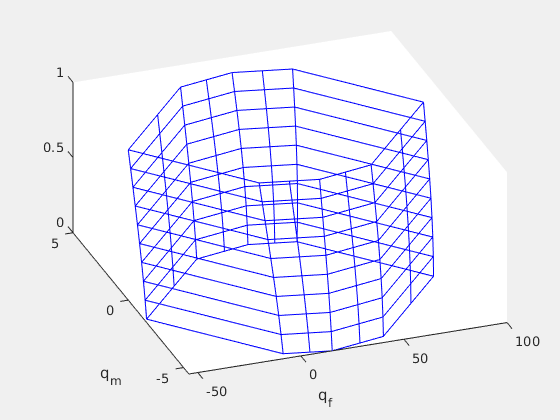

% Old method
N_as = size(boundary_af, 2);
mat_s = repmat(s, [N_as, 1]);
figure("visible", true);
hold on
plot3(boundary_af', boundary_am', mat_s, 'b');
plot3(boundary_af', boundary_am', s, 'b');

xlabel("q_f");
ylabel("q_m");
view(-20, 45);

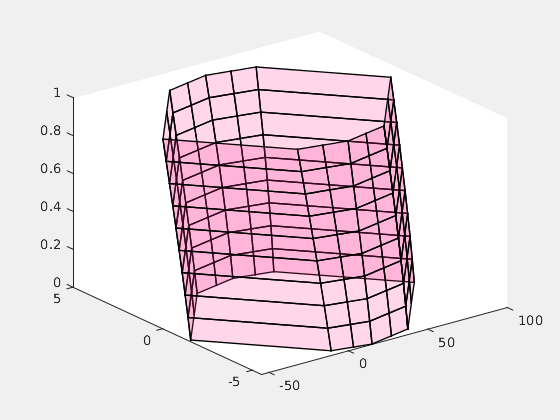

%%% New patches method
% Construct vertex matrices
X = [];
Y = [];
Z = [];
N_rxns = size(boundary_af, 2);
for i = 1 : N_poses - 1
    X_i = [
        boundary_af(i, :);
        circshift(boundary_af(i, :), 1);
        circshift(boundary_af(i+1, :), 1);
        boundary_af(i+1, :);
    ];

    Y_i = [
        boundary_am(i, :);
        circshift(boundary_am(i, :), 1);
        circshift(boundary_am(i+1, :), 1);
        boundary_am(i+1, :);
    ];

    Z_i = [
        mat_s_T(i, i_bndry);
        mat_s_T(i, i_bndry);
        mat_s_T(i+1, i_bndry);
        mat_s_T(i+1, i_bndry);
    ];

    X = horzcat(X, X_i);
    Y = horzcat(Y, Y_i);
    Z = horzcat(Z, Z_i);
end

color_green = [45 182 125] / 255;
color_yellow = [255 176 0] / 255;
color_blue = [100 143 255] / 255;
color_red = [255 48 150] / 255;

% Lighter colors
% color_green = [130 205 174] / 255;
% color_yellow = [248 203 97] / 255;
% color_blue = [135 167 250] / 255;
% color_red = [230 100 164] / 255;

figure("Visible", true, "Renderer", "painters");
fill3(X, Y, Z, color_red, "facealpha", 0.2, "linewidth", 1);